Clear Workspace and Variables

clear all;
close all;
clc;

Add paths

addpath tools
addpath signals
addpath hrtf_set
addpath NatNet_SDK_4.0\

**Audio File**

This is the file which will be played for the spatial sound. The file must be stereo (2 channels) and it must be equalized to the specific user setting (e.g. equalization between the speaker diaphragm to the ears). If no equalization is available the stereo version of the unechoic music Blues_Stereo.wav or unechoic speech Speech_File_Stereo can also be used. Without equalization the user might experience the sound internalized.

Once again, AudioDeviceInfo() is used to identify the Name of the output device. This time, the corresponding NAME is used as opposed to the [ID]. 

exampleAudioFile = 'signals/Blues_EQ_Axel.wav'; 

AudioDeviceInfo()

 
INPUT DEVICES: [ID] NAME 
[0] Primary Sound Capture Driver (Windows DirectSound)
[1] Mikrofonarray (Realtek(R) Audio) (Windows DirectSound)
 
 
OUTPUT DEVICES: [ID] NAME 
[2] Primary Sound Driver (Windows DirectSound)
[3] Lautsprecher/Kopfhörer (Realtek(R) Audio) (Windows DirectSound)


**Audio Player Setup**

The section below initializes the sound drivers. The sampling frequency is taken from the sampling rate of the HRTF dataset (44.1 kHz). 

The bufferSize refers to the size of the packets that are sent to the sound card at a given instance, having a large bufferSize will result in a lot of computational processing.

A small bufferSize is desirable for a head-tracking setup since the HRTFs must be updated as soon as possible in reference to the user's head position. The frameLength

is the size of each processing unit, before the next one is computed. Keeping this short will result in very short latency in the update algorithm for head-tracking, however the major limitation is still in the bufferSize. In practice frameLength is less than or equal to the bufferSize. Keeping these variables short might improve the performance, but this must be done with careful consideration in order to avoid artefacts such as **clicks **during each transition period, the crossfade algorithm may not allow for a smooth transition in such a short interval.

In addition to this, the bufferSize of the soundcard must be checked first, using a proprietary software package, since most soundcards allow the user to adjust the bufferSize. The default settings have a bufferSize = frameLength = $$2^8 = 256$$, this correponds to 5.8 ms in latency (when $f_s$ = 44.1 kHz). 

disp('create audio player object')

create audio player object



fs = 44100; %sampling frequency

devName = "Analog (3+4) (RME Fireface UCX)"; %set the sound card device name here

bufferSize = 2^8; 

setpref('dsp','portaudioHostApi',3);

aDW = audioDeviceWriter('SampleRate', fs, 'Driver', 'DirectSound',...
    'DeviceName', devName,...
    'BufferSize', bufferSize,...
    'ChannelMappingSource', 'Auto');

disp('create file object')

create file object



frameLength=2^8;

aFR = dsp.AudioFileReader(exampleAudioFile, 'SamplesPerFrame', frameLength);

**UI Setup**

The User Interface lets the subject adjust the azimuth and elevation angles of the incoming sound. **Closing this window will stop the program from running.**

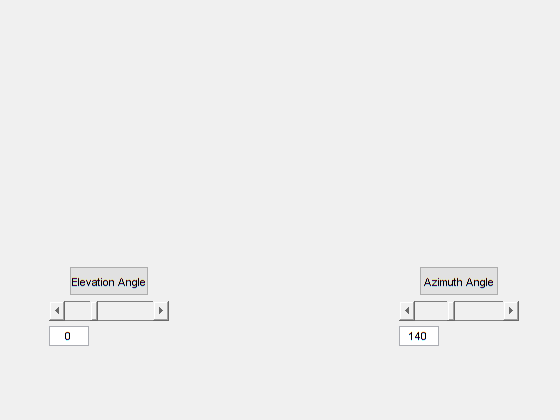

starting_az = 140; 
starting_el = 0;
starting_el_index = (10*round(starting_el/10) + 50) / 10; 

h_az_sl = uicontrol('Style', 'Slider',...
        'Min',0,'Max',355,'Value',starting_az,...
        'Position', [400 100 120 20],'SliderStep',[1/355 1/71],'Callback', ...
        'set(h_az_tf,"String",num2str(get(gcbo,"Value")))');

h_elev_sl = uicontrol('Style', 'Slider',...
        'Min',-40,'Max',90,'Value',starting_el,...
        'Position', [50 100 120 20],'SliderStep',[1/130 1/13],'Callback', ...
        'set(h_elev_tf,"String",num2str(get(gcbo,"Value")))');

h_az_tf = uicontrol('Style', 'Edit',...
        'String',num2str(h_az_sl.Value),...
        'Position', [400 75 40 20],'Callback',...
        'set(h_az_sl,"Value",str2double(get(gcbo,"String")))');

h_elev_tf = uicontrol('Style', 'Edit',...
        'String',num2str(h_elev_sl.Value),...
        'Position', [50 75 40 20],'Callback',...
        'set(h_elev_sl,"Value",str2double(get(gcbo,"String")))');

uicontrol('String','Elevation Angle', 'Position',[70 125 80 30])
uicontrol('String','Azimuth Angle', 'Position',[420 125 80 30])

**Starting Playback**

HRTF_cell.mat is the matrix that contains all the vectors for the HRTF for a given set of azimuth and elevation angles. 

The playback is buffer-based which means that the audiofile is processed in short frames of for example 256 samples. When convolving the frames of the audiofile with the HRTFs the overlap add method is used. Convolving a frame of length L with an HRTF of  length M results in a signal of length L+M-1. The first L samples are send to the sound card and the tail of the convolved signal is saved and added to the the beginning of the next iteration. This method ensures a smooth transition from frame to frame.

The updating algorithm works by crossfading the currently selected hrtf with the one used in the previous frame. For crossfading a raised cosine window is applied. The previous hrtf is included to get a smooth transition to the new angle. This adds a delay of one buffer but avoids artifacts such as clicks when jumping to a new position. 

disp('playback started')

playback started



load HRTF_cell.mat

HRTF_length = 512; % length of HRTF, can be verified by looking at the HRTF matrix

inBuffer = zeros((frameLength+HRTF_length-1),2);    % Initializing inBuffer
index = 28;                                         % Index corresponding to azimuth angle of 140 degrees
h_left_pre = HRTF_L{starting_el_index}(:,index);          % Defining the left hrtf
h_right_pre = HRTF_R{starting_el_index}(:,index);         % Defining the right hrtf


Initialize the drivers for Head Tracking

% create an instance of the natnet client class
natnetclient = natnet;

% connect the client to the server (multicast over local loopback) -
% modify for your network
natnetclient.HostIP = '127.0.0.1';
natnetclient.ClientIP = '127.0.0.1';
natnetclient.ConnectionType = 'Multicast';
natnetclient.connect;

while ~aFR.isDone

    %read chunk of target and maskers
    audioData = step(aFR);
    
    drawnow;                               
    % drawnow forces MATLAB to refresh and register the new
    % values of the sliders

    source = get(h_az_sl,'Value');                  % source reads the azimuth angle from the slider
    
    check_val = NatNetPollingSample(natnetclient.getFrame);
    
    ang = round(check_val);

    ang = source - ang;

    if ang < 0
        ang = 360 + ang;
    end

    if ang >= 360
        ang = ang - 360;
    end

    drawnow;
    v_angle = get(h_elev_sl,"Value");               % v_angle reads the elevation angle from the slider
    v_angle_index = (10*round(v_angle/10) + 50) / 10;     
    % This operation encodes the vertical angle so that it can be read
    % easily by the angle_index function. More details on this can be seen
    % in the angle_index() function.

    [az_index] = angle_index(v_angle_index, ang);            
    % since the elevation angle is already known, angle_index() taken the
    % encoded elevation angle and the azimuth angle and returns the index
    % corresponding to the azimuth angle for a given elevation. 
    
    h_left = crossfade(h_left_pre,HRTF_L{v_angle_index}(:,az_index));
    h_right = crossfade(h_right_pre,HRTF_R{v_angle_index}(:,az_index));
    % these variables contain the tail of the hrtf of the previous buffer
    % and the first half of the new buffer with a crossfade operation in
    % between to avoid abrupt jumps. 


    [audioData, outBuffer] = overlapAdd(audioData, h_left,h_right, inBuffer);
    % overlapAdd() is responsible for combining the previous buffer to the
    % current buffer. It does this by setting the first frameLength/2 samples as 
    % inBuffer and then the remaining samples as the convolution between
    % the current hrtf and the current chunk of audio.

    % finally, the processed audio is sent to the soundcard (actual playback)
    numUnderrun = step(aDW,audioData);
    inBuffer = outBuffer;           
    % The output Buffer then becomes the input Buffer for the next loop

    h_left_pre = h_left;
    h_right_pre = h_right;
    % The same applies to the HRTFs

    if numUnderrun > 0
        fprintf('Audio writer queue was underrun by %d samples.\n',numUnderrun);
    end
    
    % This is a useful IF statement as it check if the audio writer is able
    % to send the data to the soundcard without any dropouts, missing audio chunks. 


end

Audio writer queue was underrun by 512 samples.
Audio writer queue was underrun by 768 samples.
Audio writer queue was underrun by 768 samples.
Audio writer queue was underrun by 256 samples.


Error using matlab.ui.control.UIControl/get
Invalid or deleted object.